T= readtable("C:\Users\user\MATLAB\Projects\untitled\resources\project\EskomAnalysisFold\South Africa Load data TN.xlsx","VariableNamingRule", "preserve",'PreserveVariableNames',true);
T.Properties.VariableNames={'Date','Hour','Day','NettSentout'};

if ~isdatetime(T.Date)
    T.Date = datetime(T.Date, 'InputFormat', 'dd-MM-yyyy');
end

% Extract the year and week number from the Date column
T.Year = year(T.Date);
T.Week = week(T.Date);
T.Day = day(T.Date);
T.Month = month(T.Date);
T.Hour =hour(T.Date);


## Daily analysis

% Find the highest hourly total for each day in each month
highestHourlyDay = varfun(@max, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');

% Display the first few rows of the result to verify
disp(head(highestHourlyDay));

    Year    Month    Day    GroupCount    max_NettSentout
    ____    _____    ___    __________    _______________

    1988      1       1         24             14354     
    1988      1       2         24             14119     
    1988      1       3         24             13073     
    1988      1       4         24             15778     
    1988      1       5         24             16276     
    1988      1       6         24             16478     
    1988      1       7         24             16569     
    1988      1       8         24             16842     



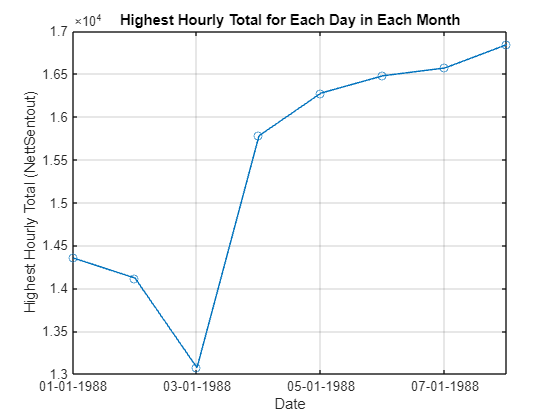

% Convert the year, month, and day columns back to a datetime array
highestHourlyDay.Date = datetime(highestHourlyDay.Year, highestHourlyDay.Month, highestHourlyDay.Day);

%Plot the highest hourly totals
figure;
plot(head(highestHourlyDay.Date), head(highestHourlyDay.max_NettSentout), '-o');
xlabel('Date');
ylabel('Highest Hourly Total (NettSentout)');
title('Highest Hourly Total for Each Day in Each Month');
grid on;
xtickformat('dd-MM-yyyy');

## Weekly analysis

%Find the highest hourly total for each week
highestHourlyWeek = varfun(@max, T,...
    'GroupingVariables', {'Year', 'Week'},...
    'InputVariables', 'NettSentout');

% Display the first few rows of the result to verify
disp(head(highestHourlyWeek));

    Year    Week    GroupCount    max_NettSentout
    ____    ____    __________    _______________

    1988     1          48             14354     
    1988     2         168             16842     
    1988     3         168             17574     
    1988     4         168             17516     
    1988     5         168             17628     
    1988     6         168             17795     
    1988     7         168             17944     
    1988     8         168             17970     



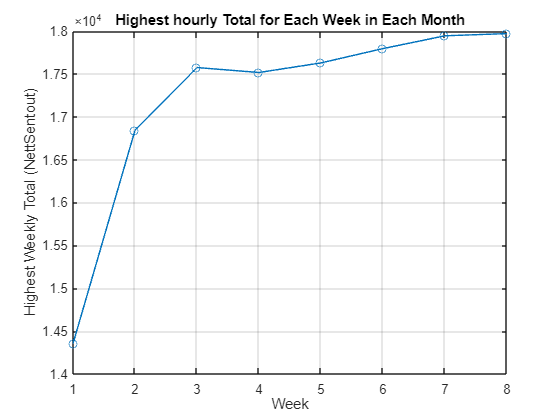



% Plot the graph for the highest hour in a week
figure;
plot(head(highestHourlyWeek.Week), head(highestHourlyWeek.max_NettSentout), '-o');
xlabel('Week');
ylabel('Highest Weekly Total (NettSentout)');
title('Highest hourly Total for Each Week in Each Month');
grid on;

## Monthly Analysis

peakMonthlyHours = varfun(@max, T, "GroupingVariables", {'Year', 'Month'}, InputVariables="NettSentout");

% Display few rows of the result
disp(head(peakMonthlyHours));

    Year    Month    GroupCount    max_NettSentout
    ____    _____    __________    _______________

    1988      1         744             17628     
    1988      2         696             17970     
    1988      3         744             18093     
    1988      4         720             18891     
    1988      5         744             19234     
    1988      6         720             20589     
    1988      7         744             20311     
    1988      8         744             19980     



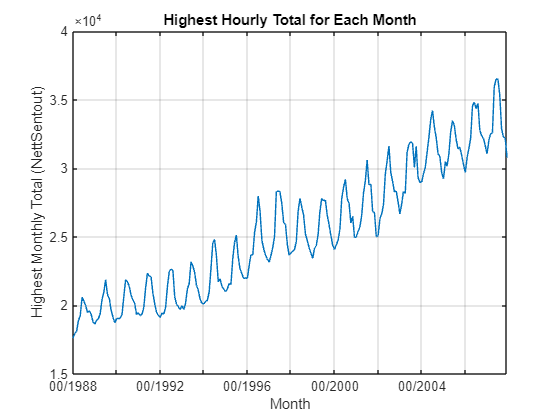

peakMonthlyHours.Date = datetime(peakMonthlyHours.Year, peakMonthlyHours.Month, 1);

% Plot the monthly peak load
figure;
plot(peakMonthlyHours.Date, peakMonthlyHours.max_NettSentout);
xlabel('Month');
ylabel('Highest Monthly Total (NettSentout)');
title('Highest Hourly Total for Each Month');
grid on;
xtickformat("mm/yyyy");

## Yearly Analysis

% Find the peak load hours for each year
peakLoadHours = varfun(@max, T, ...
    'GroupingVariables', 'Year', ...
    'InputVariables', 'NettSentout');
[peakHourlyLoads, idxHours] = max(peakLoadHours.max_NettSentout);
peakLoadHoursDay = peakLoadHours(idxHours, :);

% Display the first few rows of the result
disp(head(peakLoadHours));

    Year    GroupCount    max_NettSentout
    ____    __________    _______________

    1988       8784            20589     
    1989       8760            21871     
    1990       8760            21863     
    1991       8760            22342     
    1992       8784            22640     
    1993       8760            23169     
    1994       8760            24798     
    1995       8760            25133     



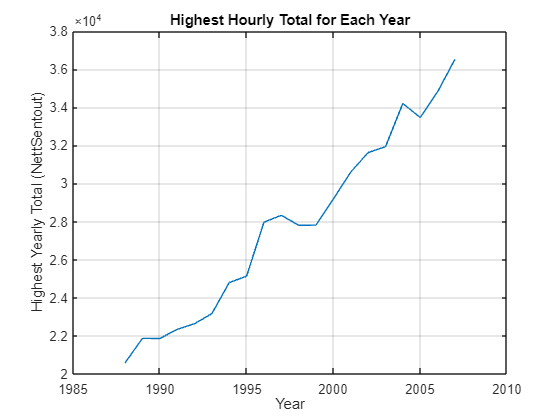

% Plot the yearly profiles
figure;
plot(peakLoadHours.Year, peakLoadHours.max_NettSentout);
xlabel('Year');
ylabel('Highest Yearly Total (NettSentout)');
title('Highest Hourly Total for Each Year');
grid on;

% As observed in the above graph (yearly load profile), we can see that the
% highest hourly total increases every year. At 1998, it was 20589. And in
% 2007, it was 36513 Nett. Though in 1998 and 1999 there was a drop in the 
% highest hourly load, it rose again just after.  


## Load factor analysis:

## Daily Load Factor

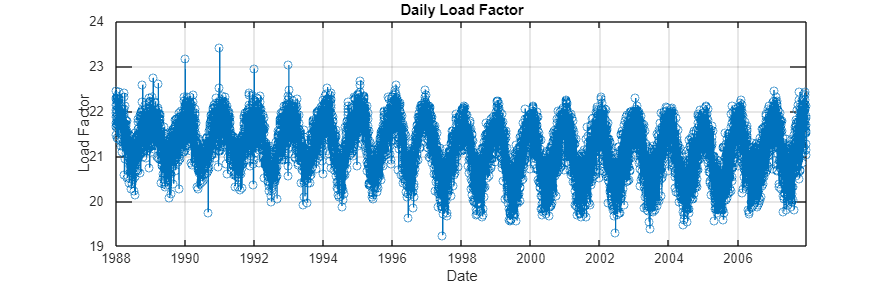

% Assuming 'T' is the table with columns: 'Year', 'Month', 'Day', 'Week', and 'NettSentout'
% Assuming 'T' is the table with columns: 'Year', 'Month', 'Day', 'Week', and 'NettSentout'

% Calculate daily max and sum
meanOfDailyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');
sumOfDailyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Month', 'Day'}, 'InputVariables', 'NettSentout');

% Calculate daily load factor
dailyLoadFactor = table(sumOfDailyLoad.sum_NettSentout ./ meanOfDailyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
dailyLoadFactorTable = [meanOfDailyLoad, dailyLoadFactor];
dailyLoadFactorTable.Date = datetime(dailyLoadFactorTable.Year, dailyLoadFactorTable.Month, dailyLoadFactorTable.Day);

% Plot daily load factor
figure('Position', [100, 100, 2200, 700]);
plot(dailyLoadFactorTable.Date, dailyLoadFactorTable.LoadFactor, '-o');
xlabel('Date');
ylabel('Load Factor');
title('Daily Load Factor');
grid on;

## Weekly Load Factor

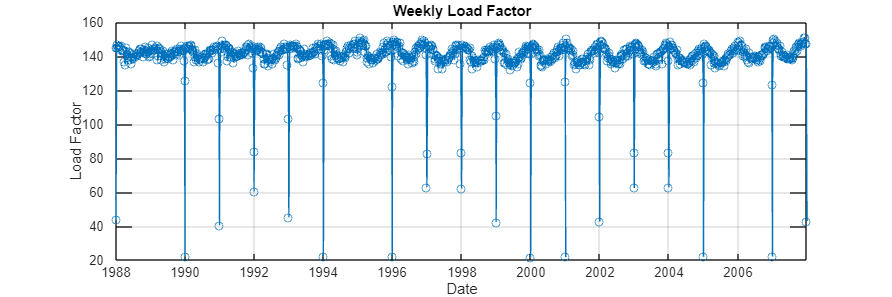

% Calculate weekly max and sum
meanOfWeeklyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Week'}, 'InputVariables', 'NettSentout');
sumOfWeeklyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Week'}, 'InputVariables', 'NettSentout');

% Calculate weekly load factor
weeklyLoadFactor = table(sumOfWeeklyLoad.sum_NettSentout ./ meanOfWeeklyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
weeklyLoadFactorTable = [meanOfWeeklyLoad, weeklyLoadFactor];
weeklyLoadFactorTable.Date = datetime(weeklyLoadFactorTable.Year, 1, 1) + calweeks(weeklyLoadFactorTable.Week - 1);

% Plot weekly load factor
figure('Position', [100, 100, 1200, 400]);
plot(weeklyLoadFactorTable.Date, weeklyLoadFactorTable.LoadFactor, '-o');
xlabel('Date');
ylabel('Load Factor');
title('Weekly Load Factor');
grid on;

## Monthly Load Factor

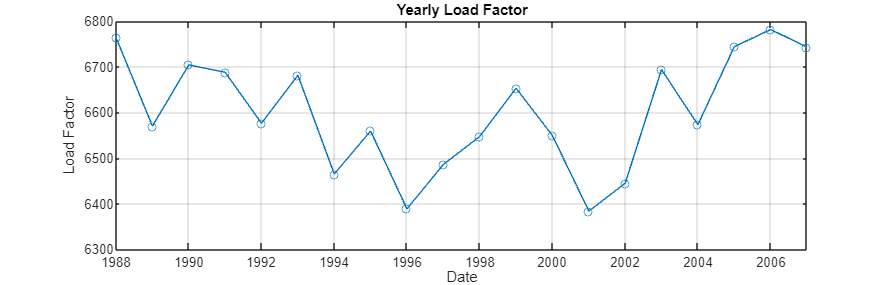

% Calculate monthly max and sum
meanOfMonthlyLoad = varfun(@max, T, 'GroupingVariables', {'Year', 'Month'}, 'InputVariables', 'NettSentout');
sumOfMonthlyLoad = varfun(@sum, T, 'GroupingVariables', {'Year', 'Month'}, 'InputVariables', 'NettSentout');

% Calculate monthly load factor
monthlyLoadFactor = table(sumOfMonthlyLoad.sum_NettSentout ./ meanOfMonthlyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
monthlyLoadFactorTable = [meanOfMonthlyLoad, monthlyLoadFactor];
monthlyLoadFactorTable.Date = datetime(monthlyLoadFactorTable.Year, monthlyLoadFactorTable.Month, 1);

% Plot monthly load factor
figure('Position', [1000, 1000, 2500, 800]);
plot(monthlyLoadFactorTable.Date, monthlyLoadFactorTable.LoadFactor);
xlabel('Date');
ylabel('Load Factor');
title('Monthly Load Factor');
grid on;

## Yearly Load Factor

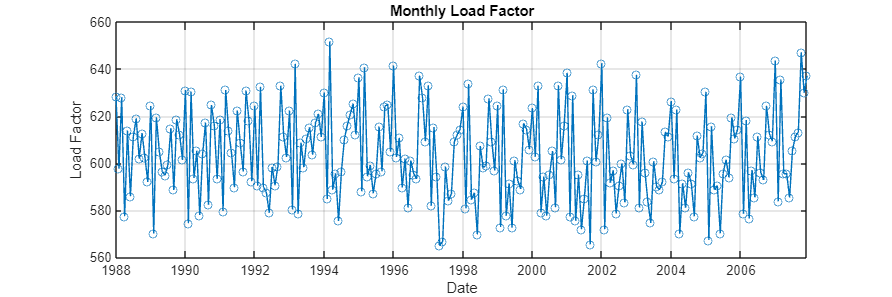


% Calculate yearly max and sum
meanOfYearlyLoad = varfun(@max, T, 'GroupingVariables', {'Year'}, 'InputVariables', 'NettSentout');
sumOfYearlyLoad = varfun(@sum, T, 'GroupingVariables', {'Year'}, 'InputVariables', 'NettSentout');

% Calculate yearly load factor
yearlyLoadFactor = table(sumOfYearlyLoad.sum_NettSentout ./ meanOfYearlyLoad.max_NettSentout, 'VariableNames',{'LoadFactor'});
yearlyLoadFactorTable = [meanOfYearlyLoad, yearlyLoadFactor];
yearlyLoadFactorTable.Date = datetime(yearlyLoadFactorTable.Year, 1, 1);

% Plot yearly load factor
figure('Position', [100, 100, 1200, 400]);
plot(yearlyLoadFactorTable.Date, yearlyLoadFactorTable.LoadFactor);
xlabel('Date');
ylabel('Load Factor');
title('Yearly Load Factor');
grid on;